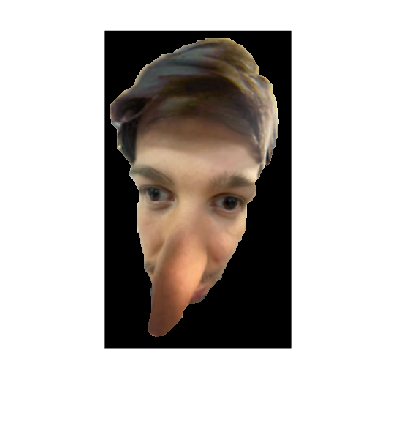

clear
% Original image and size
image = im2double(imread("images/DaNasa.png"));
originalSize = size(image);  % Get the original size of the image

% Resize the image down and up
nearestImage = imresize(imresize(image, 0.25, 'bicubic'), 4, 'nearest');
nearestImage=cat(3,double(dither(nearestImage(:,:,1))),double(dither(nearestImage(:,:,2))),double(dither(nearestImage(:,:,3))));
imDither=cat(3,double(dither(image(:,:,1))),double(dither(image(:,:,2))),double(dither(image(:,:,3))));
% Remove extra rows and columns to match the original size
[rows, cols, ~] = size(nearestImage);  % Get the current size

% Ensure it matches the original size (rows and columns)
rowsToCrop = max(0, rows - originalSize(1));  % How many extra rows to crop
colsToCrop = max(0, cols - originalSize(2));  % How many extra columns to crop

% Crop the image to the original size (both rows and columns)
nearestImage = nearestImage(1:originalSize(1), 1:originalSize(2), :);


imshow(image)

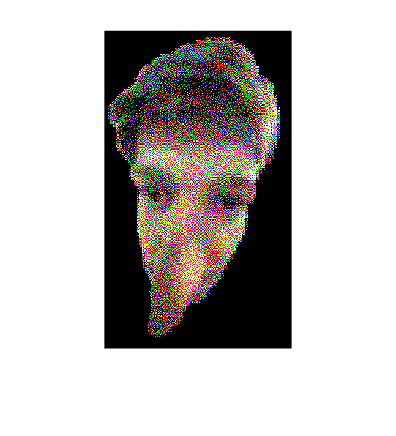

imshow(nearestImage);


%imshow(imDither);


CIED65=[95.05, 100, 108.9];
d=15.7;         % =40cm
ppi=267;        % pixels per inch for Surface Pro 6

sampPerDegree=ppi*d*tan(pi/180);
imageXYZ=rgb2xyz(rgb_filter(image));
imDitherXYZ=rgb2xyz(rgb_filter(nearestImage));

scieMap=scielab(sampPerDegree,imageXYZ,imDitherXYZ,CIED65,'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


imshow(image)

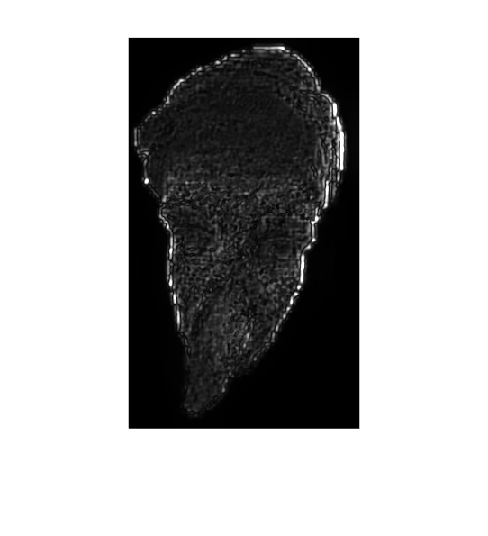

imshow(scieMap);

disp("SNR: "+snr(image,image-nearestImage))

SNR: 0.065183


disp("SNR: "+snr(image,image-imDither))

SNR: 0.2571


disp("SNR: "+snr(image,image-scieMap))
